**Задание 1.1**

clear()
load("C:\Users\vorko\OneDrive\Рабочий стол\Учеба\Учеба(финальный сем)\ident_lab1_v02.mat")
X1=[zad11.x1 zad11.x2 zad11.x3];
Y1=zad11.y;
Theta_hat1=inv(X1'*X1)*X1'*Y1

Theta_hat1 =    -2.9973
   -7.9929
    2.0066


X2=[zad12.x1 zad12.x2 zad12.x3];
Y2=zad12.y;
Theta_hat2=inv(X2'*X2)*X2'*Y2

Theta_hat2 =    -2.9919
   -7.9922
    2.0129


**Задание 1.2**

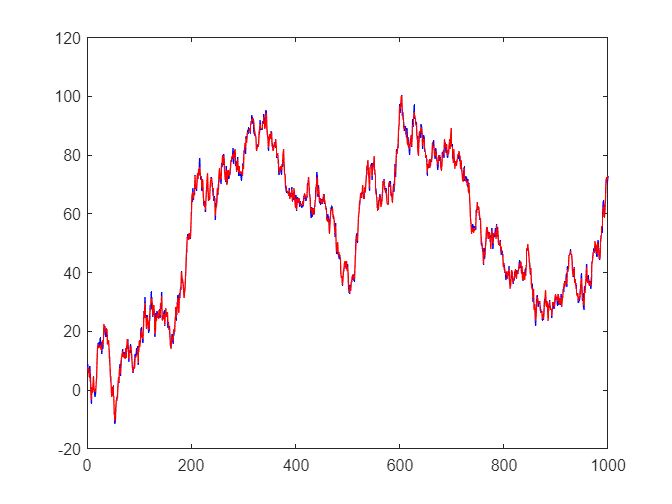

plot(Y1, 'blue')
hold on
Y_hat1=X1*Theta_hat1;
plot(Y_hat1, 'red')
hold off

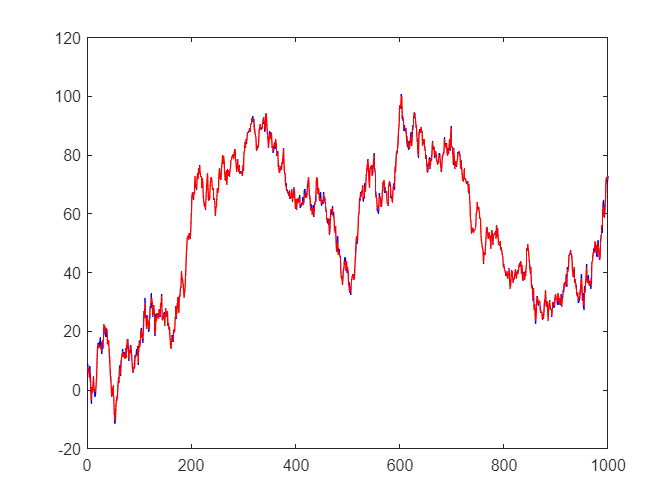


plot(Y2, 'blue')
hold on
Y_hat2=X2*Theta_hat2;
plot(Y_hat2, 'red')
hold off

**Задание 1.3**

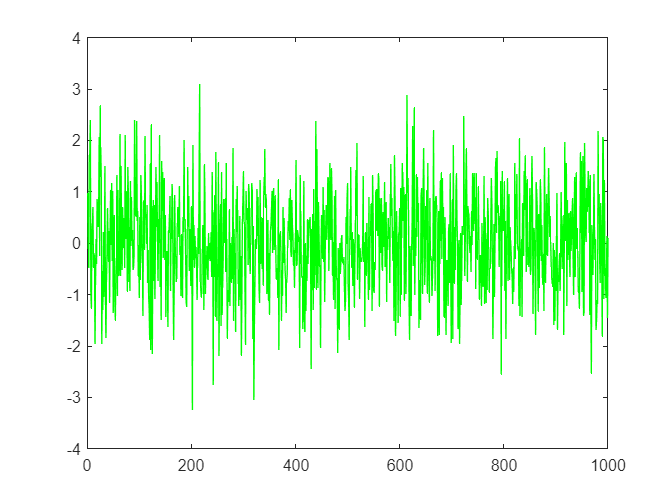

plot(Y1-Y_hat1, 'green')

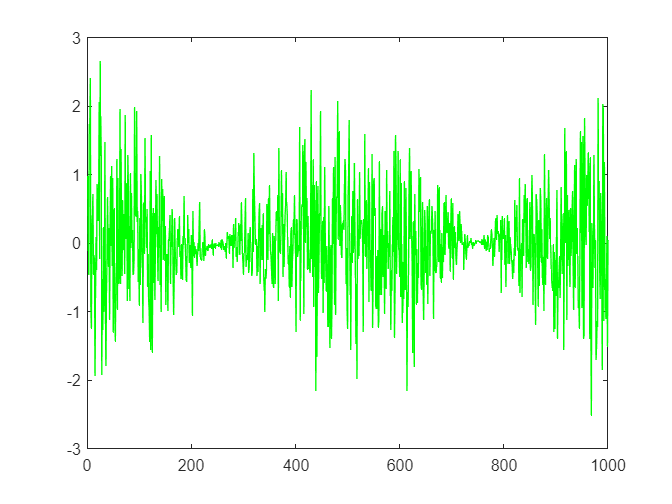

plot(Y2-Y_hat2, 'green')

Для надежности добавим коэффициент v в расчеты на случай, если мат ожидание помехи не равно нулю

% X1=[zad11.x1 zad11.x2 zad11.x3 ones(length(zad11.x1),1)];
% Y1=zad11.y;
% Theta_hat1=inv(X1'*X1)*X1'*Y1
% 
% X2=[zad12.x1 zad12.x2 zad12.x3 ones(length(zad11.x1),1)];
% Y2=zad12.y;
% Theta_hat2=inv(X2'*X2)*X2'*Y2
% 
% plot(Y1, 'blue')
% hold on
% Y_hat1=X1*Theta_hat1;
% plot(Y_hat1, 'red')
% hold off
% 
% plot(Y2, 'blue')
% hold on
% Y_hat2=X2*Theta_hat2;
% plot(Y_hat2, 'red')
% hold off
% 
% plot(Y1-Y_hat1, 'green')
% plot(Y2-Y_hat2, 'green')

**Задание 1.4**

Гипотеза 1

fprintf("Ошибка относительно усредненного выхода для измерения 1")

Ошибка относительно усредненного выхода для измерения 1

V1=Y1-Y_hat1;
E1=mean(V1);
E1/mean(Y1)*100

ans = 0.0310


fprintf("Ошибка относительно усредненного выхода для измерения 2")

Ошибка относительно усредненного выхода для измерения 2

V2=Y2-Y_hat2;
E2=mean(V2);
E2/mean(Y2)*100

ans = 0.0210

Среднестатистическая ошибка < 0.1% от среднего выходного значения => гипотеза подтверждена

Гипотеза 2

fprintf("Корреляция для измерения 1")

Корреляция для измерения 1

C11=corr(X1(:, 1), V1)

C11 = 1.4987e-14

C12=corr(X1(:, 2), V1)

C12 = 0.0325

C13=corr(X1(:, 3), V1)

C13 = -0.0373


fprintf("Корреляция для измерения 2")

Корреляция для измерения 2

C21=corr(X2(:, 1), V2)

C21 = -1.3194e-14

C22=corr(X2(:, 2), V2)

C22 = 0.0313

C23=corr(X2(:, 3), V2)

C23 = -0.0359

Корреляция вектора ошибок с вектором каждого состояния близка к нулю => эти величины можно считать взаимонезависимыми => гипотеза подтверждена

Гипотеза 3

fprintf("Определитель квадрата X для измерения 1")

Определитель квадрата X для измерения 1

det(X1'*X1)

ans = 1.2176e+12


fprintf("Определитель квадрата X для измерения 2")

Определитель квадрата X для измерения 2

det(X2'*X2) 

ans = 1.2176e+12

Из расчетов видно, что определители сильно не вырождены => гипотеза подтверждена

Гипотеза 4

fprintf("Дисперсия для 5 выборок для измерения 1")

Дисперсия для 5 выборок для измерения 1

for i = 1:length(V1)/10:length(V1)/2
   std( V1(i:i+length(V1)/2))
end

ans = 0.9739

ans = 0.9333

ans = 0.9560

ans = 0.9306

ans = 0.9349


fprintf("Дисперсия для 5 выборок для измерения 2")

Дисперсия для 5 выборок для измерения 2

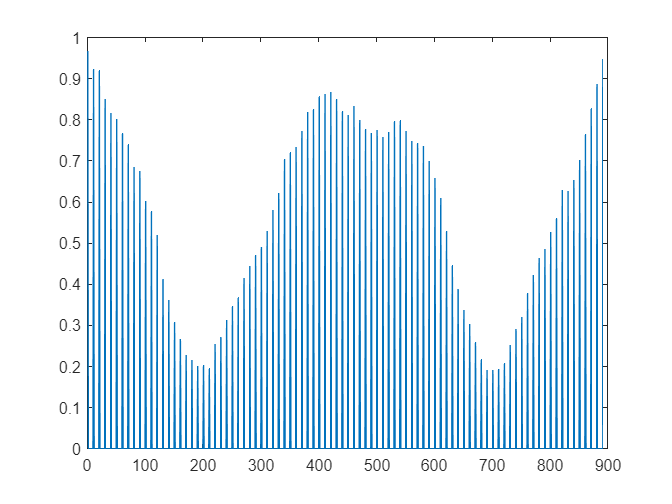

for i = 1:length(V2)/100:length(V2)-100
   Z(i)=std( V2(i:i+100));
end
plot(Z)

Из данных выборок видно, что дисперсия по 5 случайным выборокам довольно сильно совпадает => гипотеза подтверждена

Гипотеза 5

fprintf("Автокорреляция для измерения 1")

Автокорреляция для измерения 1

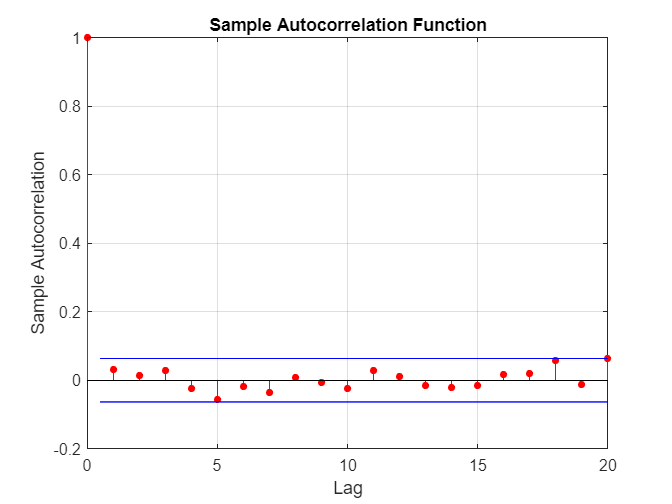

autocorr(V1)


fprintf("Автокорреляция для измерения 2")

Автокорреляция для измерения 2

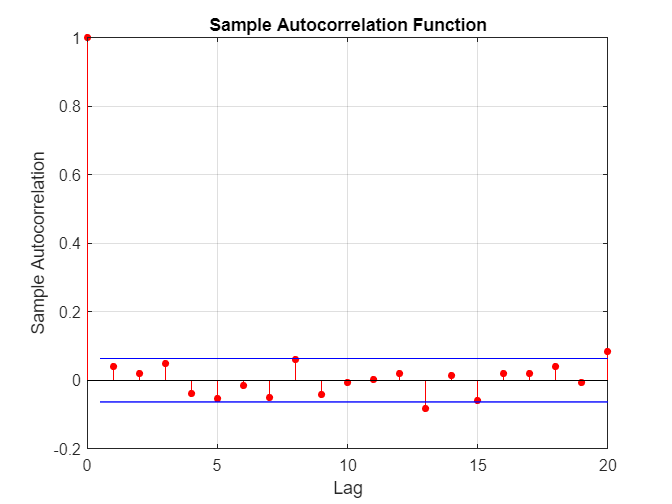

autocorr(V2)

 Из графиков видно, что втокорреляция близка к нулю => величины неавтокоррелированы => гипотеза подтвержденаzad21

Итог по гипотезам:

Подтвержденные гипотезы 1-3 означают, что найдена несмещенная оценка

Подтвержденные гипотезы 4-5 означают, что найдена эффективная оценка

**Задание 2.1**

Разделение выборки размера 14 на тренировочную размером 10 и тестовую размером 4

trainSize = 10

trainSize = 10

trainT1=[zad21.T(1) zad21.T(2) zad21.T(4) zad21.T(5) zad21.T(7) zad21.T(8) zad21.T(10) zad21.T(11) zad21.T(13) zad21.T(14)]'

trainT1 =     30
    33
    39
    42
    48
    51
    57
    60
    66
    69


trainV1=[zad21.V(1) zad21.V(2) zad21.V(4) zad21.V(5) zad21.V(7) zad21.V(8) zad21.V(10) zad21.V(11) zad21.V(13) zad21.V(14)]'

trainV1 =   322.7154
  362.2022
  449.8447
  490.0825
  559.2723
  584.1462
  641.5549
  668.3940
  709.3704
  719.0297


trainT2=[zad22.T(1) zad22.T(2) zad22.T(4) zad22.T(5) zad22.T(7) zad22.T(8) zad22.T(10) zad22.T(11) zad22.T(13) zad22.T(14)]'

trainT2 =     30
    33
    39
    42
    48
    51
    57
    60
    66
    69


trainV2=[zad22.V(1) zad22.V(2) zad22.V(4) zad22.V(5) zad22.V(7) zad22.V(8) zad22.V(10) zad22.V(11) zad22.V(13) zad22.V(14)]'

trainV2 =   336.8844
  361.4861
  432.3340
  462.6090
  521.9243
  560.8094
  630.2967
  656.5262
  726.9069
  763.6738


testSize = 4

testSize = 4

testT1=[zad21.T(3) zad21.T(6) zad21.T(9) zad21.T(12)]'

testT1 =     36
    45
    54
    63


testV1=[zad21.V(3) zad21.V(6) zad21.V(9) zad21.V(12)]'

testV1 =   404.6593
  521.2229
  615.2104
  696.3678


testT2=[zad22.T(3) zad22.T(6) zad22.T(9) zad22.T(12)]'

testT2 =     36
    45
    54
    63


testV2=[zad22.V(3) zad22.V(6) zad22.V(9) zad22.V(12)]'

testV2 =   396.5335
  494.0234
  600.3949
  698.6000


allSize = 14

allSize = 14


X11=[trainT1 ones(trainSize,1)];
Y11=trainV1;
X11_t=[testT1 ones(testSize,1)];
Y11_t=testV1;

X12=[trainT2 ones(trainSize,1)];
Y12=trainV2;
X12_t=[testT2 ones(testSize,1)];
Y12_t=testV2;

X21=[trainT1.^2 trainT1 ones(trainSize,1)];
Y21=trainV1;
X21_t=[testT1.^2 testT1 ones(testSize,1)];
Y21_t=testV1;

X22=[trainT2.^2 trainT2 ones(trainSize,1)];
Y22=trainV2;
X22_t=[testT2.^2 testT2 ones(testSize,1)];
Y22_t=testV2;

**Задание 2.2**

Параметры найденные по обучающей выборке

Theta_hat11=inv(X11'*X11)*X11'*Y11;
Theta_hat12=inv(X12'*X12)*X12'*Y12;
Theta_hat21=inv(X21'*X21)*X21'*Y21;
Theta_hat22=inv(X22'*X22)*X22'*Y22;

**Задание 2.3**

Графики построенные по тестовой выборке

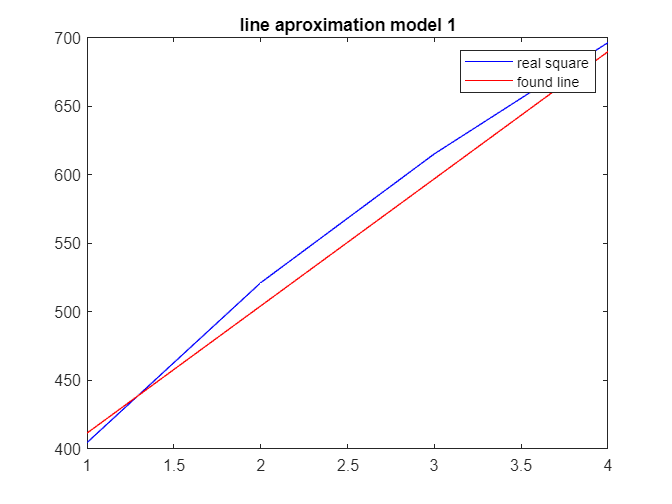

plot(Y11_t, 'blue')
hold on
Y_hat11=X11_t*Theta_hat11;
plot(Y_hat11, 'red')
title('line aproximation model 1')
legend("real square", "found line")
hold off

answer1 = std(Y_hat11-Y11_t)

answer1 = 11.6228

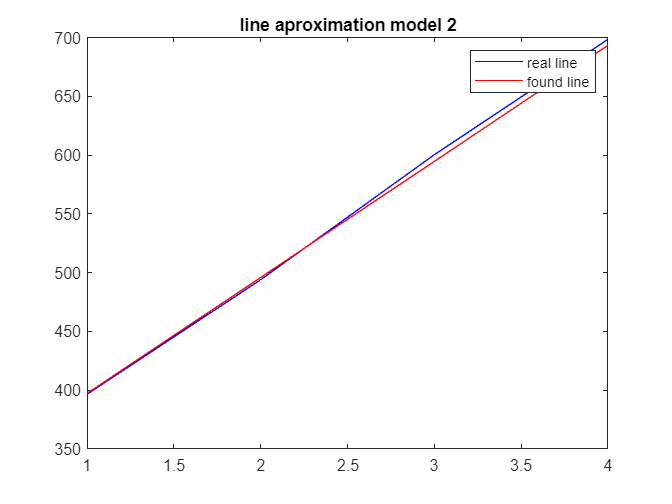


plot(Y12_t, 'blue')
hold on
Y_hat12=X12_t*Theta_hat12;
plot(Y_hat12, 'red')
title('line aproximation model 2')
legend("real line", "found line")
hold off

answer2 = std(Y_hat12-Y12_t)

answer2 = 3.9197

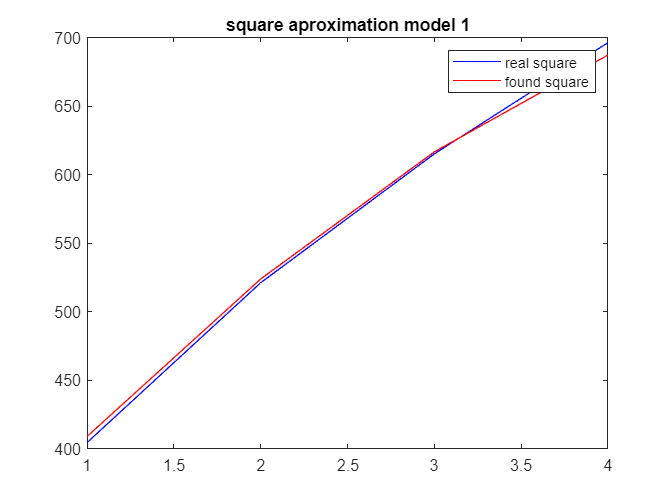


plot(Y21_t, 'blue')
hold on
Y_hat21=X21_t*Theta_hat21;
plot(Y_hat21, 'red')
title('square aproximation model 1')
legend("real square", "found square")
hold off

answer3 = std(Y_hat21-Y21_t)

answer3 = 6.0958

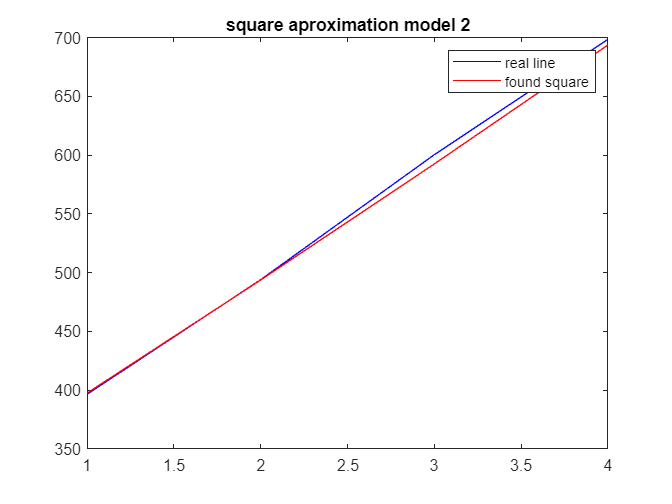


plot(Y22_t, 'blue')
hold on
Y_hat22=X22_t*Theta_hat22;
plot(Y_hat22, 'red')
title('square aproximation model 2')
legend("real line", "found square")
hold off

answer4 = std(Y_hat22-Y22_t)

answer4 = 4.1011

**Задание 2.4**

По полученным результатам получается следующий список по увеличению квадрата отклонения

1.реальная зависимость - линейная;             аппроксимация - квадратичная

std=answer2

std = 3.9197

2. реальная зависимость - линейная;             аппроксимация -  линейная

std=answer4

std = 4.1011

3. реальная зависимость - квадратичная;      аппроксимация - квадратичная 

std=answer3

std = 6.0958

4.  реальная зависимость - квадратичная;      аппроксимация - линейная 

std=answer1

std = 11.6228

**Задание 3.1**

Преобразуем уравнение: $y(x) = p_1sin(11x+p_2)  <=> y(x) = sin(11x)q_1+cos(11x)q_2  \quad при  \quad q_1=p_1cos(p_2);  \quad q_2=p_1sin(p_2) \quad y(x) = p_1sin(11x+p_2)$

 
$$y(x) = (x+p_1)/(x+p_2) <=> Y=Xq_1+q_2 \quad при \quad Y=xy-x;  \quad X=-y q_1=p_2; \quad q_1=p_1$$


zad31

zad31 = struct with fields:
       x: [0 0.0295 0.0591 0.0886 0.1182 0.1477 0.1773 0.2068 0.2364 0.2659 0.2954 0.3250 0.3545 0.3841 0.4136 0.4432 0.4727 0.5023 0.5318 0.5614 0.5909 0.6204 0.6500 0.6795 0.7091 0.7386 0.7682 0.7977 0.8273 0.8568]
       y: [5.2806 9.6233 12.9585 14.9370 15.3518 14.1592 11.4843 7.6071 2.9334 -2.0473 -6.8138 -10.8668 -13.7822 -15.2547 -15.1301 -13.4215 -10.3077 -6.1148 -1.2817 3.6856 8.2670 11.9829 14.4443 15.3935 14.7310 12.5263 9.0102 4.5508 -0.3851 -5.2806]
    func: 'y(x) = p1*sin(11.0*x+p2)'


X1=[sin(11*zad31.x') cos(11*zad31.x')]

X1 =          0    1.0000
    0.3193    0.9477
    0.6052    0.7961
    0.8277    0.5612
    0.9635    0.2675
    0.9985   -0.0541
    0.9290   -0.3701
    0.7622   -0.6474
    0.5156   -0.8569
    0.2150   -0.9766


Y1=zad31.y';

zad32

zad32 = struct with fields:
       x: [1 1.6552 2.3103 2.9655 3.6207 4.2759 4.9310 5.5862 6.2414 6.8966 7.5517 8.2069 8.8621 9.5172 10.1724 10.8276 11.4828 12.1379 12.7931 13.4483 14.1034 14.7586 15.4138 16.0690 16.7241 17.3793 18.0345 18.6897 19.3448 20]
       y: [0.4493 0.4970 0.5372 0.5714 0.6009 0.6266 0.6492 0.6692 0.6870 0.7030 0.7175 0.7306 0.7426 0.7535 0.7636 0.7728 0.7814 0.7893 0.7967 0.8036 0.8100 0.8161 0.8217 0.8270 0.8320 0.8368 0.8412 0.8455 0.8495 0.8533]
    func: 'y(x) = (x+p1)/(x+p2)'


X2=[-zad32.y' ones(length(zad32.y),1)]

X2 =    -0.4493    1.0000
   -0.4970    1.0000
   -0.5372    1.0000
   -0.5714    1.0000
   -0.6009    1.0000
   -0.6266    1.0000
   -0.6492    1.0000
   -0.6692    1.0000
   -0.6870    1.0000
   -0.7030    1.0000


Y2=zad32.y'.*zad32.x'-zad32.x';

**Задание 3.2**

Theta_hat1=inv(X1'*X1)*X1'*Y1

Theta_hat1 =    14.4663
    5.2806


Theta_hat2=inv(X2'*X2)*X2'*Y2

Theta_hat2 =     5.9000
    2.1000


**Задание 3.3**

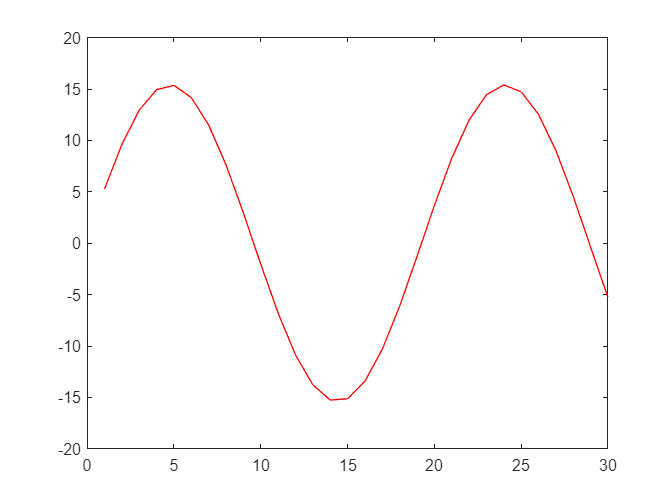

plot(Y1, 'blue')
hold on
Y_hat1=X1*Theta_hat1;
plot(Y_hat1, 'red')
hold off

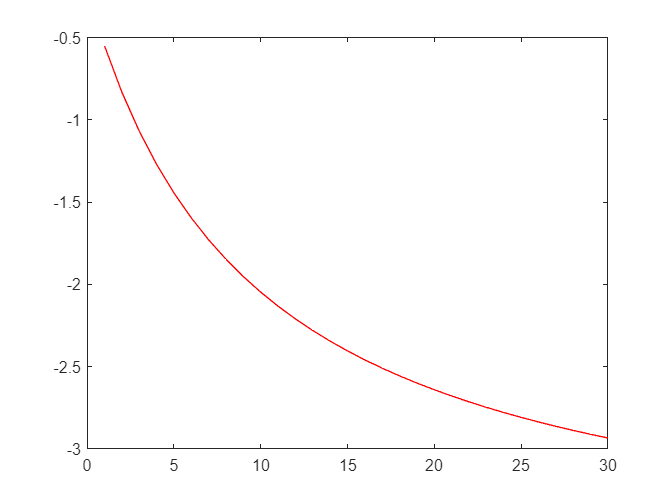


plot(Y2, 'blue')
hold on
Y_hat2=X2*Theta_hat2;
plot(Y_hat2, 'red')
hold off

**Оценка p**

q1 = Theta_hat1(1);
q2 = Theta_hat1(2);
syms p1 p2
eqn1=q1==p1*cos(p2);
eqn2=q2==p1*sin(p2);
P=solve([eqn1, eqn2], [p1, p2]);
p1 = double(P.p1)

p1 =    15.4000
  -15.4000


p2 = double(P.p2)

p2 =     0.3500
   -2.7916


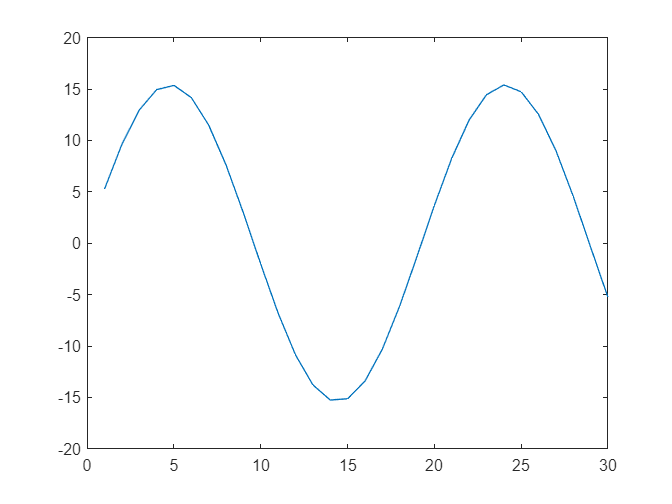

plot(p1(1)*sin(11*zad31.x+p2(1)))

plot(p1(2)*sin(11*zad31.x+p2(2)))